## 1. The `score1 `and `score2 `variables in Homework3.mat contain scores for 100 subjects on two different tests. Fit a linear model (*y*= *ax*+ *b*) to these data, attempting to predict `score2 `from `score1`. Visualize the data using a scatter plot and visualize the fitted model using a line. Report the estimated parameters in the figure title.

% load file and variables score1, score2
file = matfile('Homework3.mat');
score1 = file.score1;
score2 = file.score2;

% try to fit the model to the data using OLS method
% score1 plays the role of x, score2 - role of y
% score2 = a * score1 + b
% the chosen model is a linearized model -> it can be expressed using simple matrix notation;
% construct the regressor matrix:
X = [score1(:) ones(length(score1), 1)];

%{ 
-----explanation-----
x = [x1 x2 ... x1000] - 1*1000
X = [x1 1; x2 1; ...; x1000 1] - 1000*2
X' = [x1 x2 ... x1000; 1 1 ... 1] - 2*1000
w: w * X' = y or (w is a row and y is a row)
w: X * w = y' (w is a column and y is a column)
    X'*X * w = X' * y';
    w = inv(X'*X)*X' * y';
w = [w1; w2] = 2*1
X*inv(X) = inv(X)*X = I - identity matrix.
-----explanation-----
%}

% find the free parameters of the model 
% using OLS estimation (ordinary least-squares):
wL = inv(X'*X) * X' * score2(:);

% display the weights
fprintf('weights for y(x) = a*x + b: [a = %f, b = %f]', wL(1), wL(2)); 

weights for y(x) = a*x + b: [a = 0.298206, b = 67.033974]


% define the model using weights
yLModel = X * wL;

% calculate the squared error, achieved by the yModel
sqErr = sum((score2' - yLModel).^2);

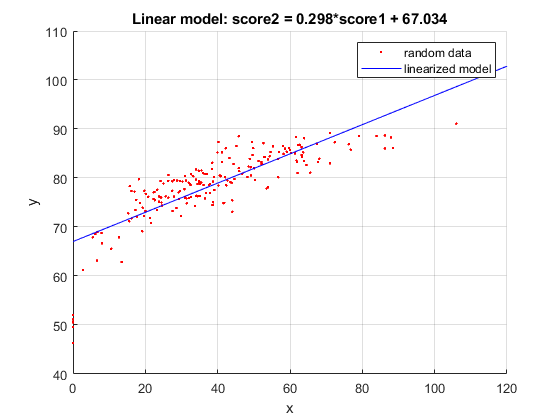

% visualize
figure;
hold on;
grid;
% visualize the data using a scatter plot
scatter(score1, score2, 'r.');
% save current axis (for x and y axes)
ax = axis;

% get limits for x ax, divide the interval into 100, convert to column
xLM = linspace(ax(1), ax(2), 100)';
yLM = [xLM ones(length(xLM), 1)] * wL;
% visualize the fitted model using a line
plot(xLM, yLM, 'b-');
legend('random data', 'linearized model');
xlabel('x');
ylabel('y');
% report the estimated parameters in the figure title
title(sprintf('Linear model: score2 = %.3f*score1 + %.3f', wL(1), wL(2)));

## 2. Redo problem 1, this time using a quadratic model (*y*=*ax^*2+*bx*+*c*).

% try to fit the model to the data using OLS method
% score1 plays the role of x, score2 - role of y
% score2 = a * score1 + b
% the chosen model is a linearized model -> it can be expressed using simple matrix notation;
% construct the regressor matrix:
% 1st column consist of quadrants of score1
XQ = score1(:).^2;
% add 2nd column - score1 values
XQ(:, end+1) = score1(:);
% add 3rd column - one values (multiply with free term - c coefficient)
XQ(:, end+1) = 1;

% find the free parameters of the model 
% using OLS estimation (ordinary least-squares):
wQ = inv(XQ'*XQ) * XQ' * score2(:);

% display the weights
fprintf('weights for y(x) = a*x^2 + b*x + c: [a = %f, b = %f, c = %f]', wQ(1), wQ(2), wQ(3)); 

weights for y(x) = a*x^2 + b*x + c: [a = -0.004426, b = 0.680811, c = 60.493052]


% define the model using weights
yQModel = XQ * wQ;

% calculate the squared error, achieved by the yModel
sqErrQ = sum((score2' - yQModel).^2);

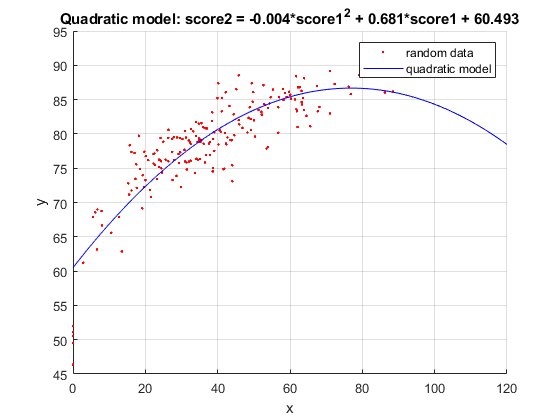

% visualize
figure;
hold on;
grid;
% visualize the data using a scatter plot
scatter(score1, score2, 'r.');
% save current axis (for x and y axes)
axQ = axis;

% get limits for x ax, divide the interval into 100, convert to column
xQM = linspace(axQ(1), axQ(2), 100)';
% 3 columns -> x^2 * w(1), x * w(2), 1 * w(3)
yQM = [xQM.^2 xQM ones(length(xQM), 1)] * wQ;
% visualize the fitted model using a line
plot(xQM, yQM, 'b-');
legend('random data', 'quadratic model');
xlabel('x');
ylabel('y');
% report the estimated parameters in the figure title
title(sprintf('Quadratic model: score2 = %.3f*score1^2 + %.3f*score1 + %.3f', wQ(1), wQ(2), wQ(3)));

## 3. Redo problem 1, this time using the model*y*=*a*x^n*+*b*. Start from two different initial seeds: *a*= 1, *n*=1, *b*= 0 and *a*= 10, *n*= 7, *b*= 100. Plot the model that achieves a lower squared error using a regular line and plot the other model using a dashed line.

% random data is ready:
% x = score1
% y = score2
% we have to calculate 3 parameters: a, n, b using nonlinear optimization

% define optimization options
options = optimset('Display', 'iter', 'FunValCheck', 'on', ...
    'MaxFunEvals', Inf, 'MaxIter', Inf, ...      
    'TolFun', 1e-6);
 
% define bounds for the parameters
%            a       n       b
paramslb = [-inf   -inf    -inf];    % lower bound
paramsub = [inf     inf     inf];    % upper bound

% define the 1st initial seed
%           a        n       b
params1 = [1.0      1.0     0.0];

% define the 2nd initial seed
%           a        n       b
params2 = [10.0     7.0    100.0];

% estimate free parameters of the model (a, n, b)
% using nonlinear optimization
% define a function that calculates that parameters for a model
% inputs are vector of parameters and vector of x-values
modelfun = @(pVect, xVect) pVect(1) * xVect.^pVect(2) + pVect(3);

% fit the model for the 1st seed
[params1, resnorm1, residual1, exitflag1, output1] = ...
    lsqcurvefit(modelfun, params1, score1, score2, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4          350877                      9.33e+05
     1          8          142784             10       1.96e+05      
     2         12           50428             20       7.63e+04      
     3         16         3081.33        24.6048       7.46e+03      
     4         20         3081.33        5.49811       7.46e+03      
     5         24          2952.7        1.37453       2.94e+04      
     6         28         2328.91       0.343632            321      
     7         32         2138.52       0.687264       4.79e+03      
     8         36         1953.21        1.37453       1.55e+04      
     9         40         1698.71        1.37453       1.12e+04      
    10         44         1698.71        3.19799       1.12e+04      
    11         48          1576.4       0.687264       2.19e+03      
    12         52         1518.7


% fit the model for the 2nd seed
[params2, resnorm2, residual2, exitflag2, output2] = ...
    lsqcurvefit(modelfun, params2, score1, score2, paramslb, paramsub, options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          4     3.10275e+30                      1.43e+31
     1          8     2.13314e+16             10       2.57e+22      
     2         12         98712.3    8.29157e-07       3.74e+11      

Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<

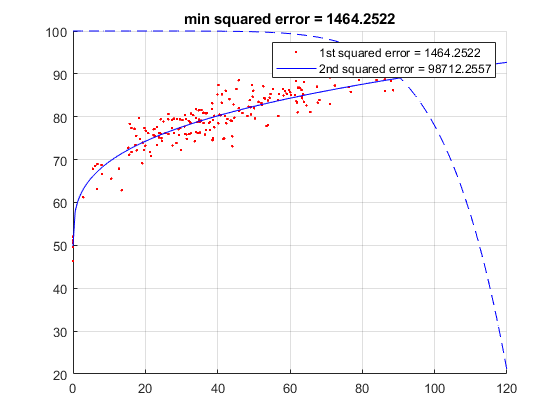


% visualize
figure;
hold on;
grid;
% visualize the input data using a scatter plot
scatter(score1, score2, 'r.');
% save current axis (for x and y axes); 
% divide x-ax into 200 points
ax = axis;
xx = linspace(ax(1), ax(2), 200);

% calculate models for the 1st and 2nd seeds
yModel1 = modelfun(params1, xx);
yModel2 = modelfun(params2, xx);

% draw plots for 1st and 2nd fit models
plot1 = plot(xx, yModel1, 'b-');
plot2 = plot(xx, yModel2, 'b-');

% lower squared error -> a regular line (the better model)
% the other model -> a dashed line
if (resnorm1 < resnorm2)
    set(plot2, 'LineStyle', '--');
else
    set(plot1, 'LineStyle', '--');
end
title(sprintf('min squared error = %.4f', min(resnorm1, resnorm2)));

% output calculated squared error values
legend(sprintf('1st squared error = %.4f', resnorm1), sprintf('2nd squared error = %.4f', resnorm2));

## 4. Perform gradient descent to fit the model described in Problem 1 (see the lecture notes for Stats Lecture4). (Hint: The amount by which to update the weights is a tricky issue. After computing the gradient vector, normalize it to have a length of one. Then update the weights by a small fraction of this vector.) Report to the command window the parameter estimates obtained by your gradient descent routine. Confirm that they are more or less identical to the parameter estimates you obtained in Problem 1. 

% gradient descent for a linear model
% score2 = a * score1 + b;

% first, set all the weights to some initial value (e.g. all zeros);
% then, compute the gradient and update the weights 
% by subtracting some small fraction of the gradient; 
% repeat the weight-updating process until the error stops decreasing.

% construct the regressor matrix with 2 columns (x-score1 and ones) [X]
% and array of data [Y]
X = [score1(:) ones(length(score1), 1)];
Y = score2(:);

wGD = gdweights(X, Y);

% output the current weights and weights for OLS linear model
fprintf('GD weights for y(x) = a*x + b: [a = %f, b = %f]', wGD(1), wGD(2)); 

GD weights for y(x) = a*x + b: [a = 0.293207, b = 67.033835]

fprintf('OLS weights for y(x) = a*x + b: [a = %f, b = %f]', wL(1), wL(2)); 

OLS weights for y(x) = a*x + b: [a = 0.298206, b = 67.033974]

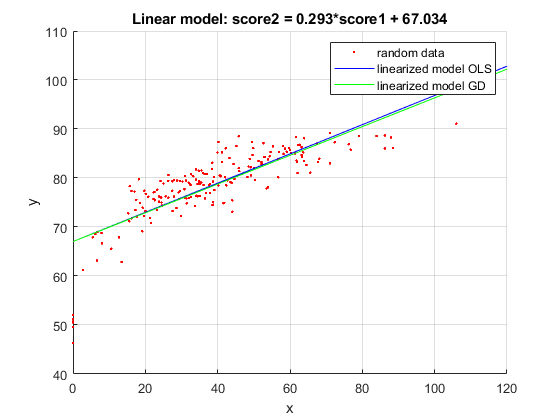

% visualize
figure;
hold on;
grid;
% visualize the data using a scatter plot
scatter(score1, score2, 'r.');
% save current axis (for x and y axes)
ax = axis;

% get limits for x ax, divide the interval into 100, convert to column
xGD = linspace(ax(1), ax(2), 100)';
yGD = [xGD ones(length(xGD), 1)] * wGD;
% visualize the fitted model using a line
plot(xLM, yLM, 'b-');
plot(xGD, yGD, 'g-');
legend('random data', 'linearized model OLS', 'linearized model GD');
xlabel('x');
ylabel('y');
% report the estimated parameters in the figure title
title(sprintf('Linear model: score2 = %.3f*score1 + %.3f', wGD(1), wGD(2)));

% the gdweights function for matrixes X, Y will compute weights 
% for linear fit model
% using gradient descent with default weights modifying step = 0.01;

function weights = gdweights(X, Y)
    % default step to modify the weights
    defstep = 0.01;

    % initialize weights and store previous calue of sq error
    wCur = zeros(2, 1);
    wOld = zeros(2, 1);
    sqErrOld = Inf;

    % start a loop until error starts increasing
    while 1
    
        % compute current squared error
        sqErrCur = sum((Y - X * wCur).^2);
    
        % quit the loop, if previous sqErr is less (better) than current sqErr
        if sqErrOld <= sqErrCur
            break;
        end
    
        % save current sqErr and weights into old and then modify current
        % weights
        wOld = wCur;
        sqErrOld = sqErrCur;
    
        % gradient descent vector
        gradVect = 2 * X' * (X * wCur - Y);
    
        % gradient vector for updating the weights
        gradVect = gradVect / sqrt(sum(gradVect.^2));
    
        % update weights
        wCur = wCur - defstep * gradVect;
    end

    % result - weights from the pre-last step (before worse sq err value is met)
    weights = wOld;
end